# Hull and Place Field Visualization

## Settings

ANIMAL controls which animal this script analyzes

animal = 'HPa';
processdata = true;

## Process convex hull data?

In this section, we determine whether or not to process a new set of convex hull data. Otherwise, we simply read from the harddrive.

if processdata
    generateconvexhull(animal,1:8,'checkmode',false);
end

Using animal info at /Volumes/Colliculus/HP_8dayExpt/HPExpt/HPa_direct/ 
Generating HPa 1 4 1 1
Generating HPa 1 4 1 2
Generating HPa 1 4 1 3
Generating HPa 1 4 1 4
Generating HPa 1 4 1 5
Generating HPa 1 4 1 6
Generating HPa 1 4 4 1
Generating HPa 1 4 4 2
Generating HPa 1 4 4 3
Generating HPa 1 4 4 5
Generating HPa 1 4 4 6
Generating HPa 1 4 4 7
Generating HPa 1 4 4 9
Generating HPa 1 4 4 10
Generating HPa 1 4 4 11
Generating HPa 1 4 4 12
Generating HPa 1 4 4 13
Generating HPa 1 4 8 1
Generating HPa 1 4 9 1
Generating HPa 1 4 14 1
Generating HPa 1 4 15 1
Generating HPa 1 4 15 2
Generating HPa 1 4 16 1
Generating HPa 1 4 16 2
Generating HPa 1 4 17 2
Generating HPa 1 4 18 2
Generating HPa 1 4 18 3
Generating HPa 1 6 1 1
Generating HPa 1 6 1 2
Generating HPa 1 6 1 3
Generating HPa 1 6 1 4
1 6 4 6
Generating HPa 1 6 4 7
Generating HPa 1 6 4 9
Generating HPa 1 6 4 10
Generating HPa 1 6 4 11
Generating HPa 1 6 4 12
Generating HPa 1 6 4 13
Generating HPa 1 6 6 1
Generating HPa 1 6 8 1
Genera

## Import Data

This section simply acquires the data, before we head off into plotting

ainfo = animaldef(animal);

Using animal info at /Volumes/Colliculus/HP_8dayExpt/HPExpt/HPa_direct/ 


chull = loaddatastruct(ainfo{2:3},'convexhull');
searchresults = cellfetch(chull,'xticks'); % used to find indices to iterate over
searchresults = searchresults.index';
cinfo = loaddatastruct(ainfo{2:3},'cellinfo');
tagresults = cellfetch(cinfo,'tag2');

## Examine

This section examines each cell.

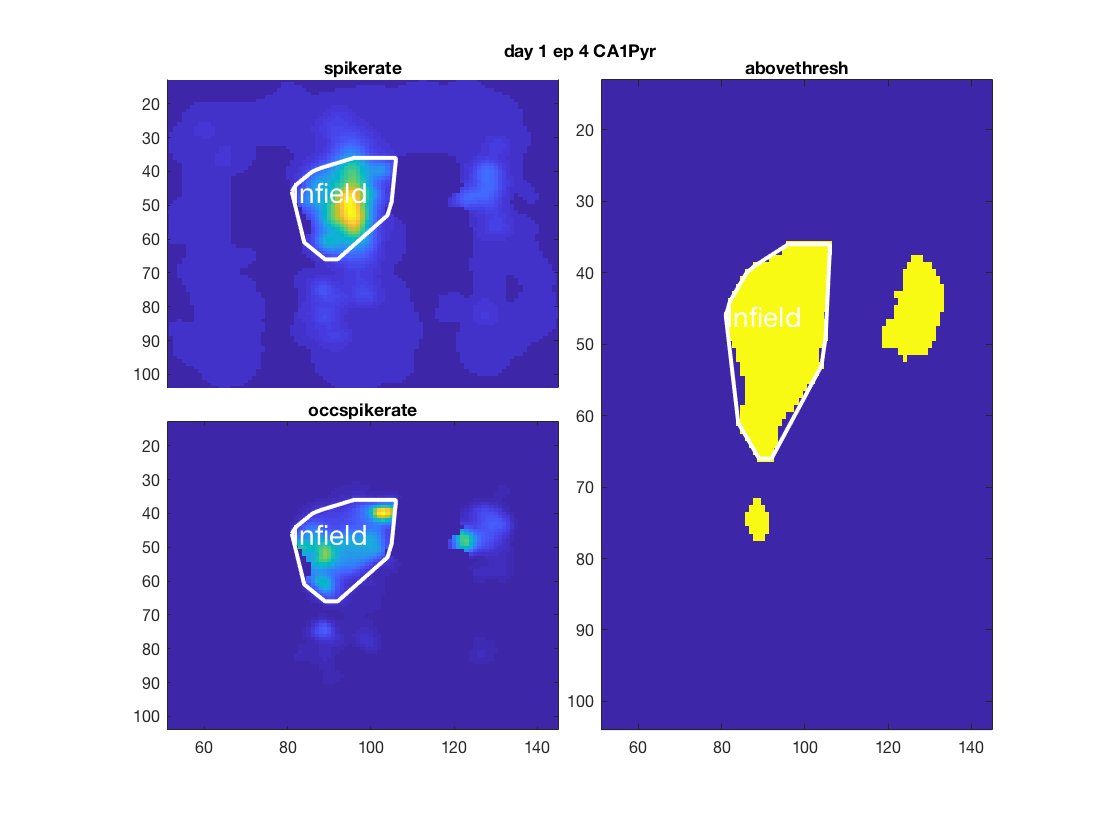

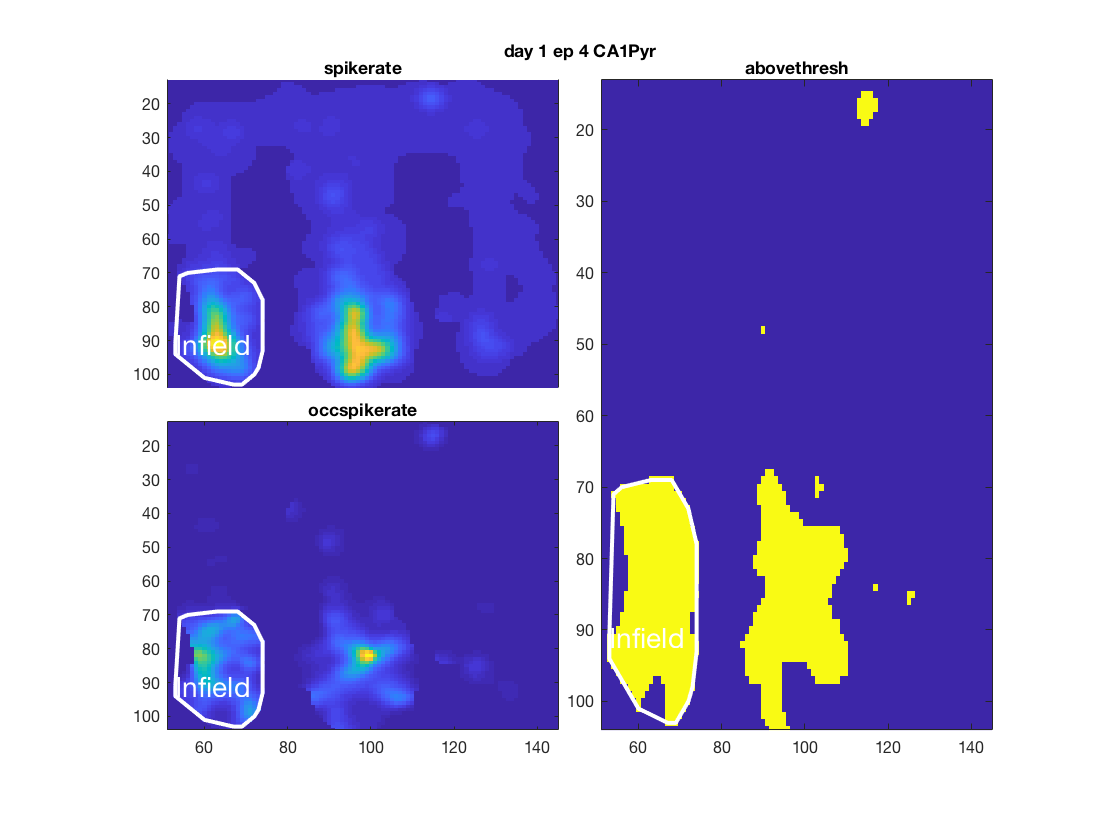

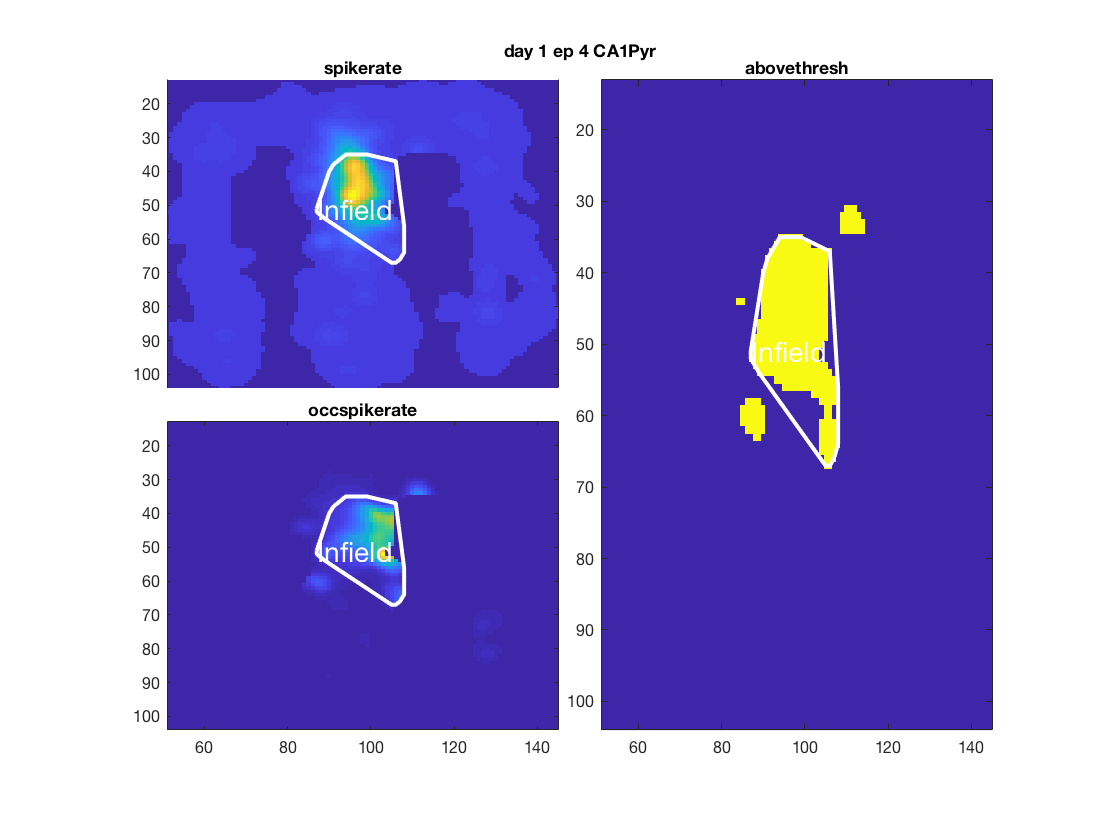

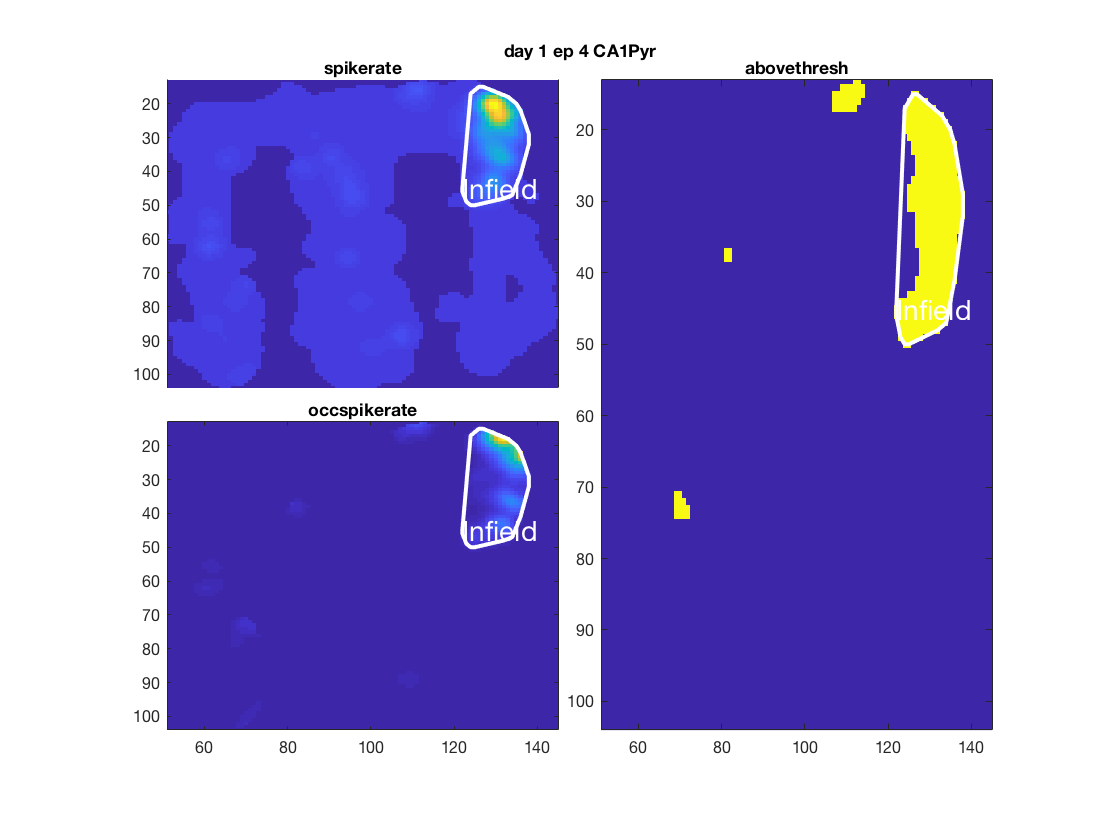

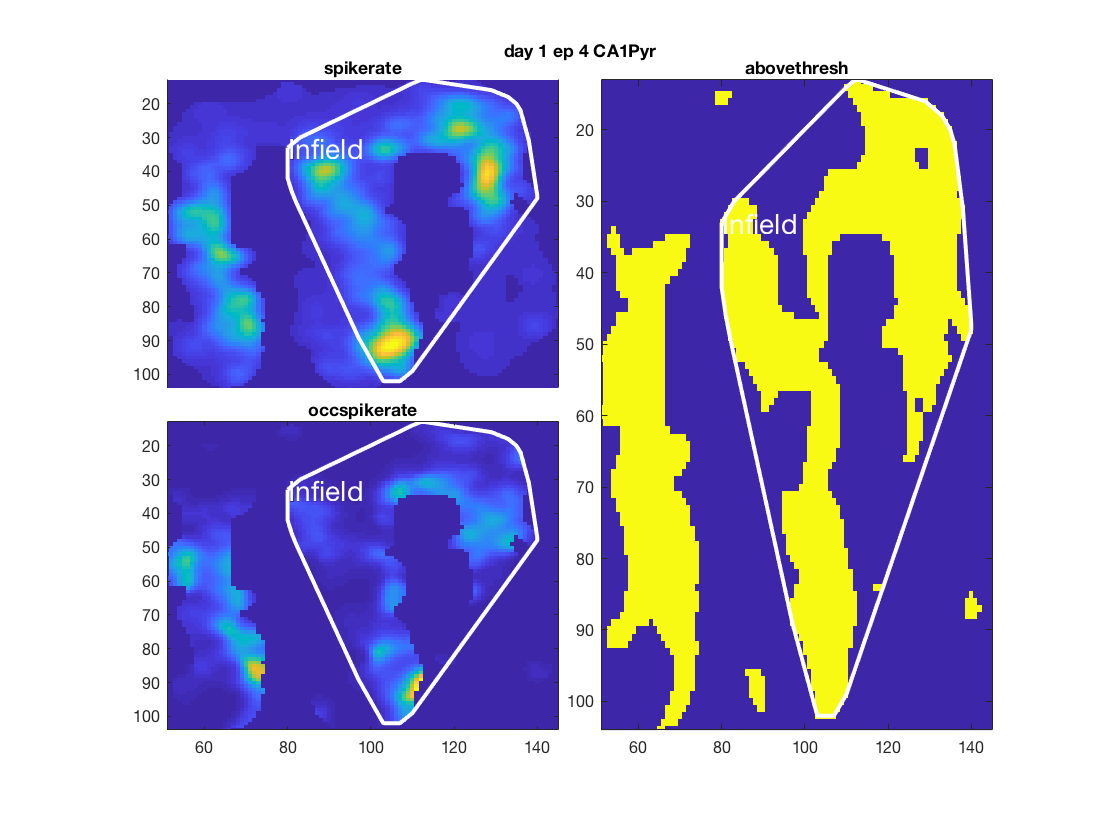

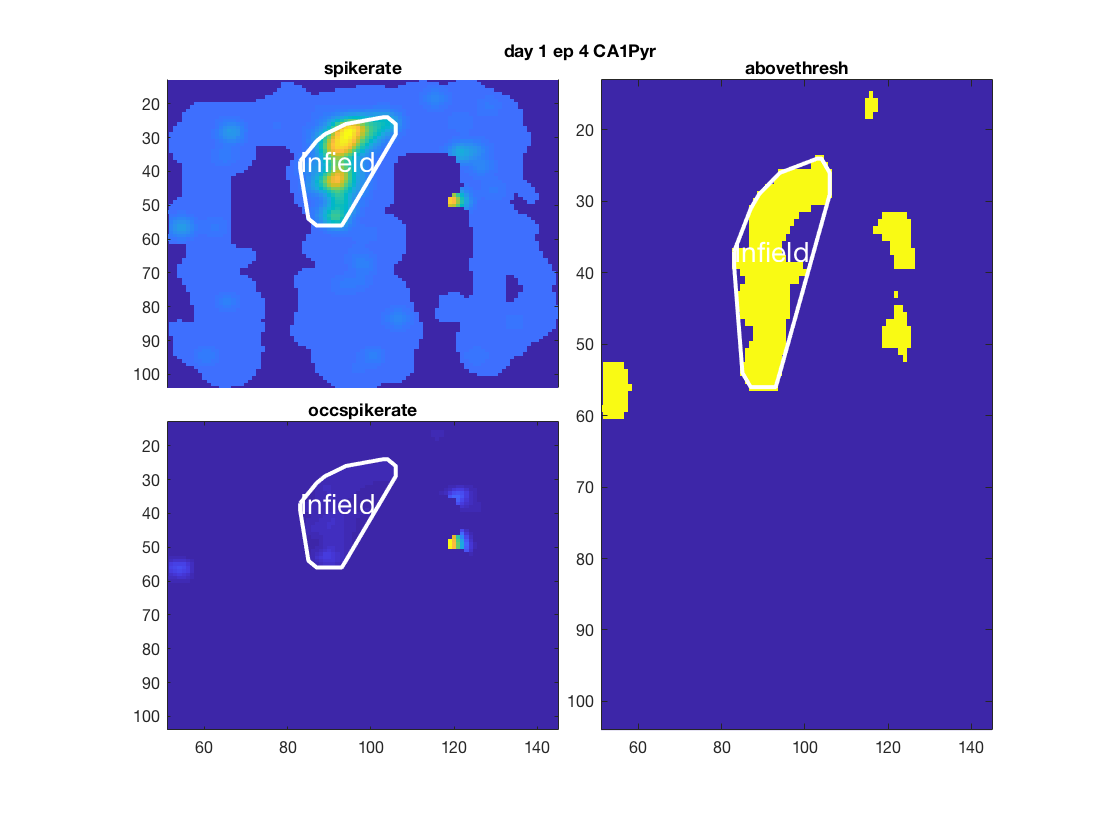

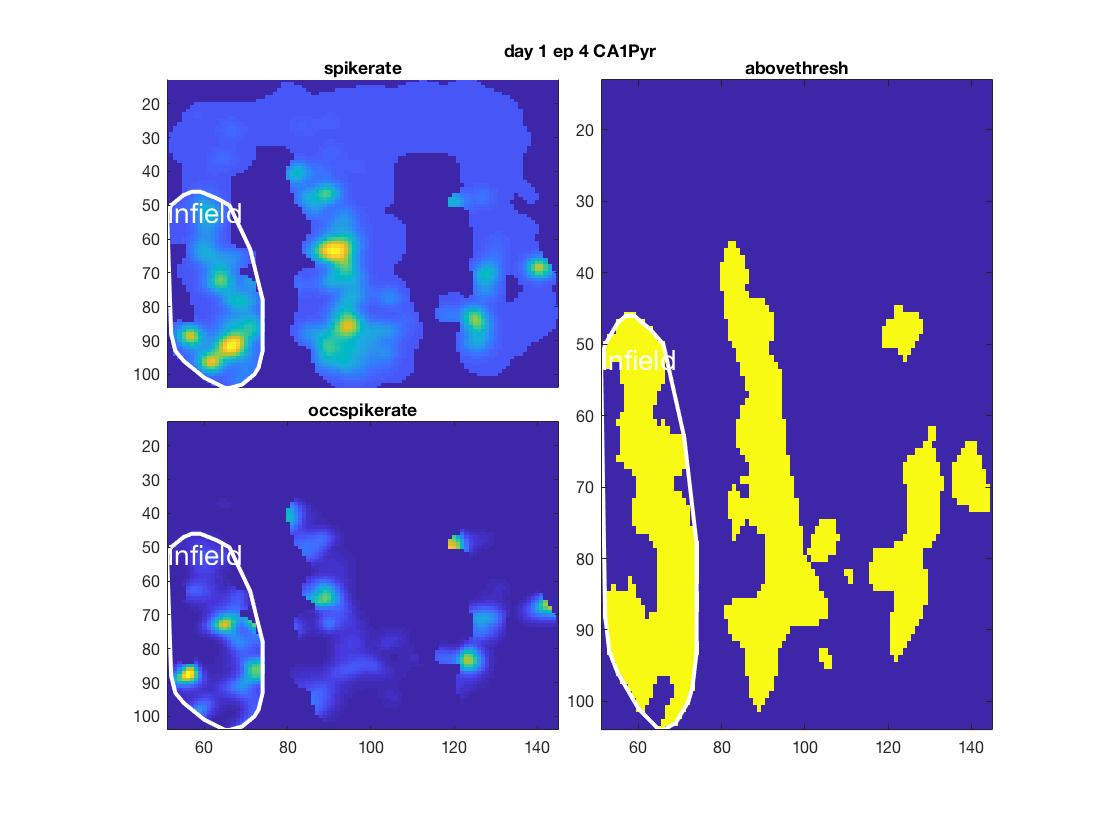

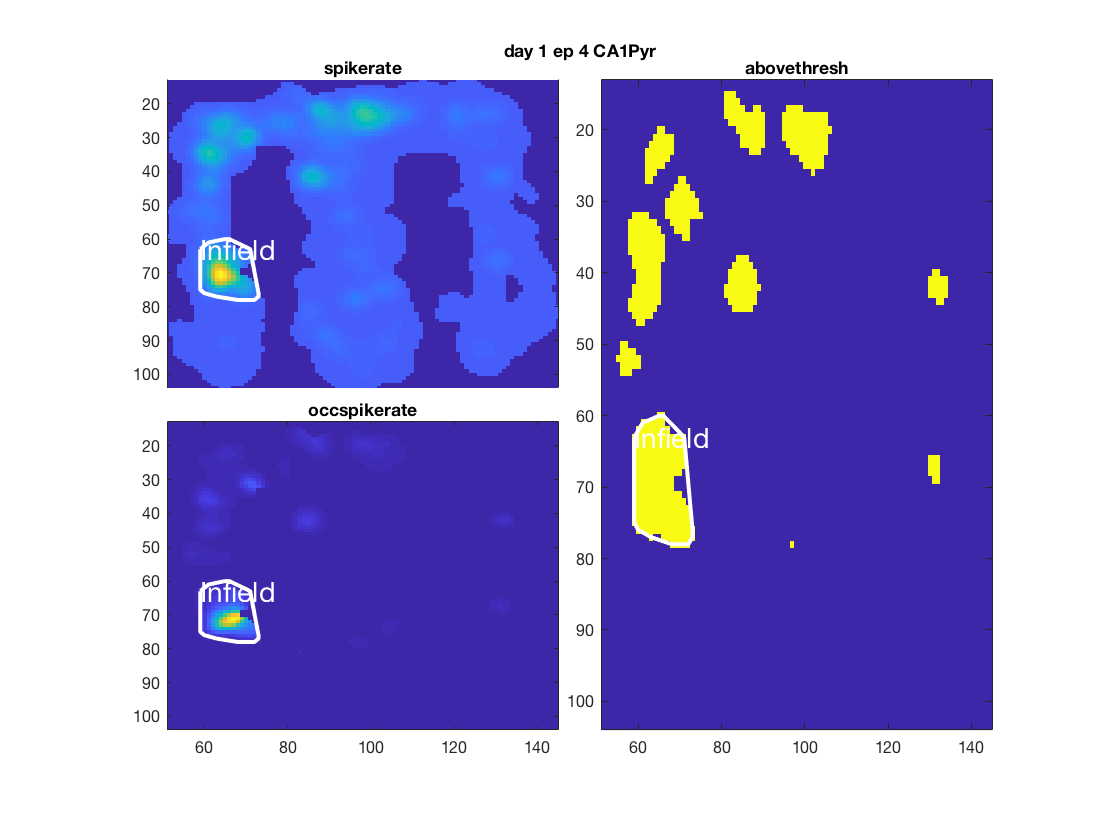

cnt=0;

for cind = searchresults
    cnt=cnt+1;
    fig(sprintf('Results %s %d %d %d %d',animal,cind));
    ind = ismember(tagresults.index,searchresults(:,cnt)','rows');
    plotelement(chull{cind(1)}{cind(2)}{cind(3)}{cind(4)},cind,tagresults.values{ind});
    if cnt==20; break; end
end

## Sub-functions

Function: plotelement

Purpose : takes each cell and plots the various aspects of the fields and derived hull, so we can check the quality.

function plotelement(chull,cind,tag)
    
    if nargin<3; tag=''; end
    
    set(0,'defaultAxesFontSize',8);
    
    % FILL ME IN
    nestplot(2,2,1,'xspacing',0.1);
    singleplot(chull,'spikerate');
    xax=get(gca,'xaxis');
    xax.Visible='off';
    nestplot(2,2,3);
    singleplot(chull,'occspikerate');
    nestplot(2,2,{1:2,2});
    singleplot(chull,'abovethresh');
    title(nestgroup,sprintf('day %d ep %d %s',cind(1:2),tag));
    
    
    function singleplot(chull,what)
        hold off;
        imagesc(chull.xticks,chull.yticks,chull.(what));
        axis( [min(chull.xticks) max(chull.xticks) min(chull.yticks) max(chull.yticks)]);
        hold on;
        p=plot(chull.posconvhull(:,1),chull.posconvhull(:,2),'w-','linewidth',2,'markersize',1,'markerfacecolor','white');
        hold on;
        text(chull.posconvhull(end,1),chull.posconvhull(end,2),'Infield','Color','white','FontSize',14);
        title(what);
    end
end